# Classification challenge

Erik Norlin

% Using Matlabs deep learning toolbox to classify digits.
% Code is essentially only settings for the package to run.
% Most of the settings used can be found here: 
% https://se.mathworks.com/help/deeplearning/ug/create-simple-deep-learning-network-for-classification.html
% https://se.mathworks.com/help/deeplearning/ref/trainnetwork.html

% Loading training, validation and test set
[xTrain, tTrain, xValid, tValid, xTest, tTest] = LoadMNIST(3);

Preparing MNIST data...
MNIST data preparation complete.


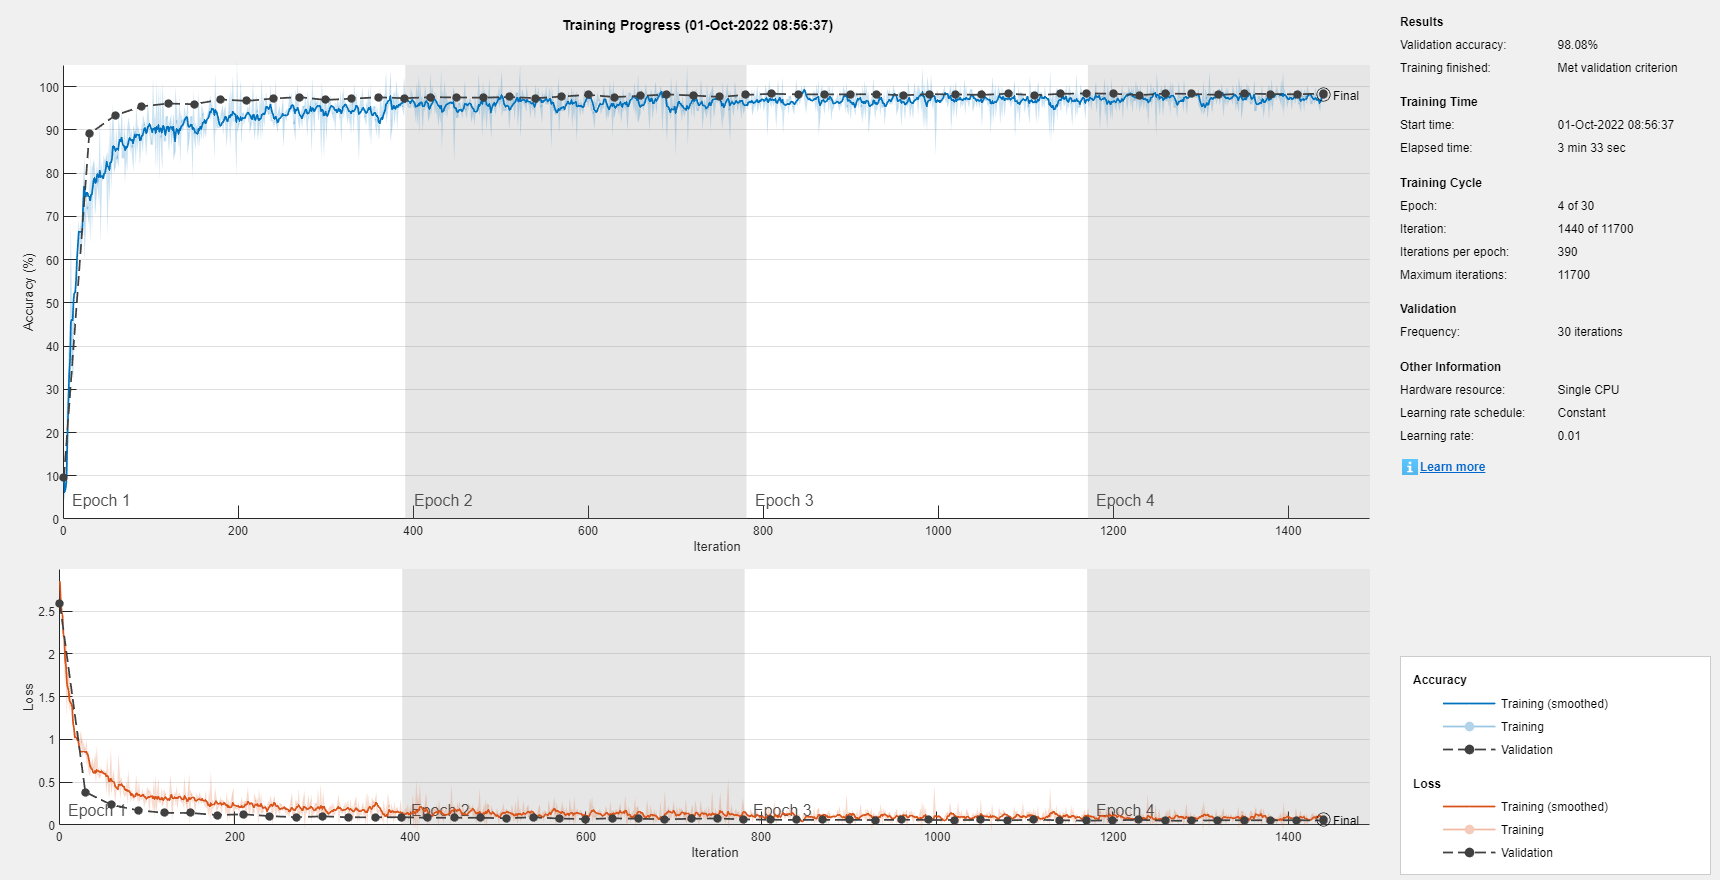

xTest2 = loadmnist2();

% Processing training set to prevent overfitting during training
imageAugmenter = imageDataAugmenter( ...
    'RandRotation',[-20,20], ...
    'RandXTranslation',[-3 3], ...
    'RandYTranslation',[-3 3]);
imageSize = [28 28 1];
augTrain = augmentedImageDatastore(imageSize,xTrain,tTrain,'DataAugmentation',imageAugmenter);

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'Momentum',0.9, ...
    'MaxEpochs',30, ...
    'ValidationPatience',5, ...
    'ValidationData',{xValid,tValid}, ...
    'Shuffle','every-epoch', ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

net = trainNetwork(augTrain,layers,options);

tPredict = classify(net,xTest2);
writematrix(tPredict,"classifications.csv")